## Aum audio signal analysis

% My Aum
[x,fs] = audioread("myOM1.mp4")

x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


fs = 44100

%x = x(:,1); % considering only 1 channel
N = length(x); % N -> total number of samples
t = (0:N-1)/fs;
% fs -> number of samples per second
N/fs % gives the duration of the audio file

ans = 13.1657

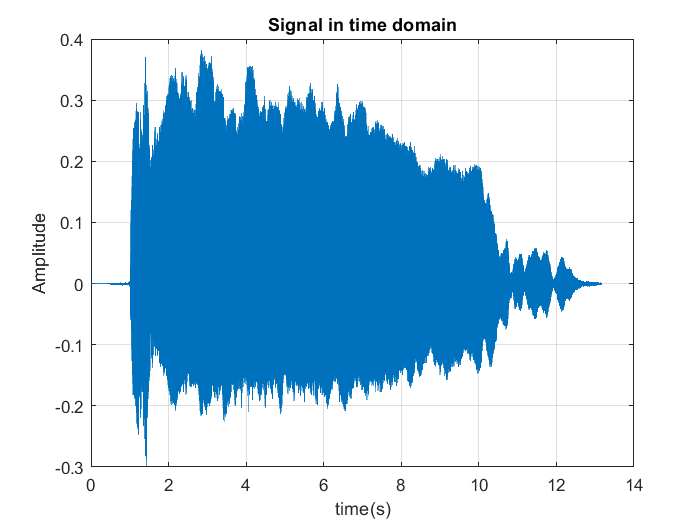

% plot time domain signal
plot(t,x)
grid on
xlabel("time(s)");
ylabel("Amplitude")
title("Signal in time domain");

% stats information
minValue = min(x)

minValue = -0.2985

maxValue = max(x)

maxValue = 0.3810

meanValue = mean(x)

meanValue = -5.5918e-04

stdValue = std(x)

stdValue = 0.1029

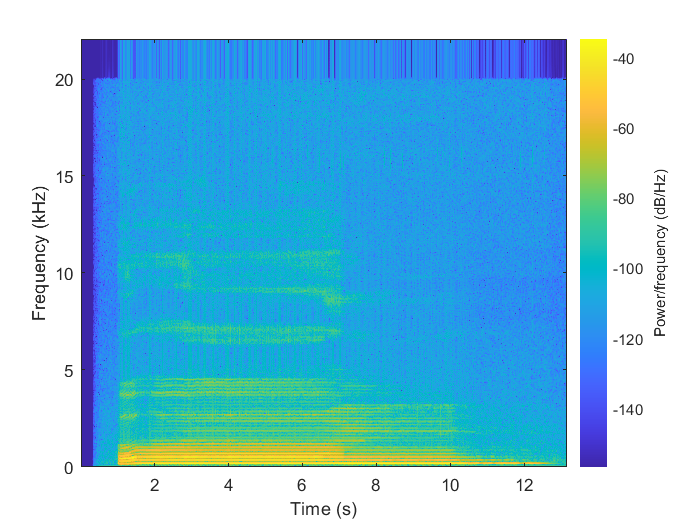

spectrogram(x, 1024, 512, 1024, fs, 'yaxis')

%% Aum audio signal analysis
% Aum by Sri Sri Rava Shankar
[x,fs] = audioread("OMgood.mp4")

x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


fs = 44100

%x = x(:,1); % considering only 1 channel
N = length(x); % N -> total number of samples
t = (0:N-1)/fs;
% fs -> number of samples per second
N/fs % gives the duration of the audio file

ans = 7.5000

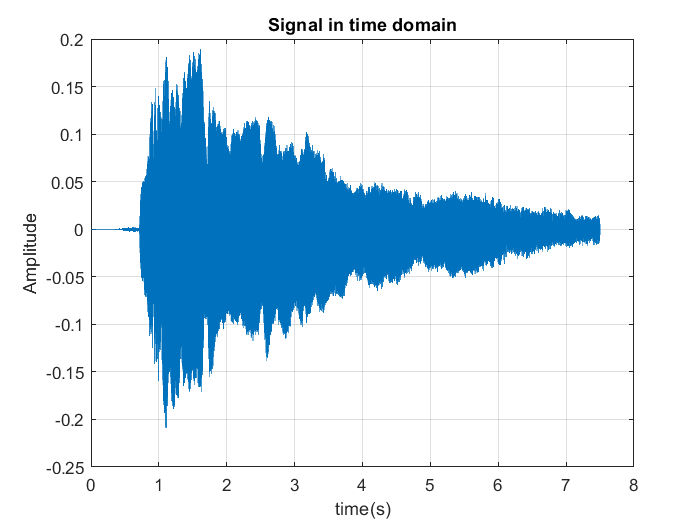

% plot time domain signal
plot(t,x)
grid on
xlabel("time(s)");
ylabel("Amplitude")
title("Signal in time domain");

% stats information
minValue = min(x)

minValue = -0.2094

maxValue = max(x)

maxValue = 0.1886

meanValue = mean(x)

meanValue = -5.7596e-04

stdValue = std(x)

stdValue = 0.0356

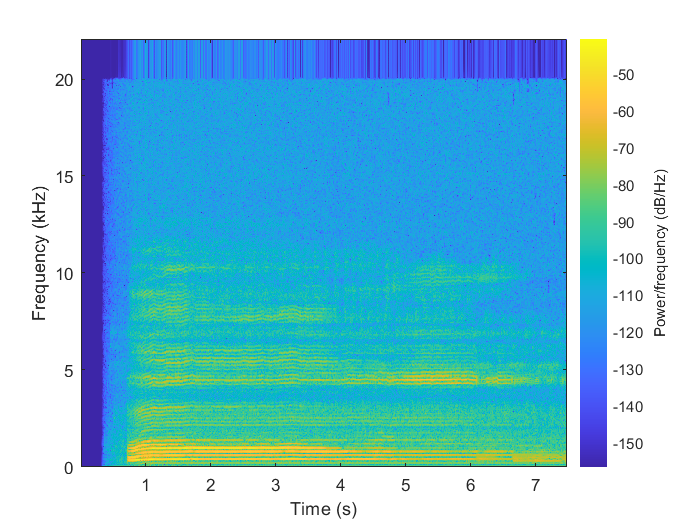

spectrogram(x, 1024, 512, 1024, fs, 'yaxis')

## Krishna Flute music


[x,fs] = audioread("KrishnaMusicW.wav")

x =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


fs = 44100

x = x(:,1); % considering only 1 channel
N = length(x); % N -> total number of samples
t = (0:N-1)/fs;
% fs -> number of samples per second
N/fs % gives the duration of the audio file

ans = 60.6273

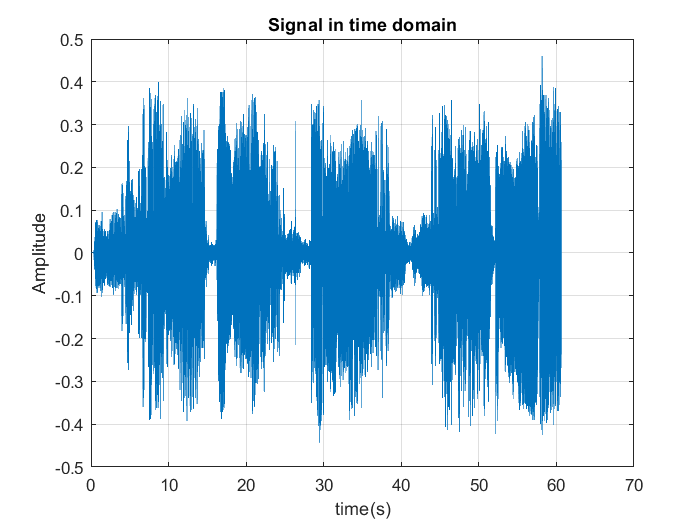

% plot time domain signal
plot(t,x)
grid on
xlabel("time(s)");
ylabel("Amplitude")
title("Signal in time domain");

% stats information
minValue = min(x)

minValue = -0.4433

maxValue = max(x)

maxValue = 0.4596

meanValue = mean(x)

meanValue = -4.3953e-04

stdValue = std(x)

stdValue = 0.1155

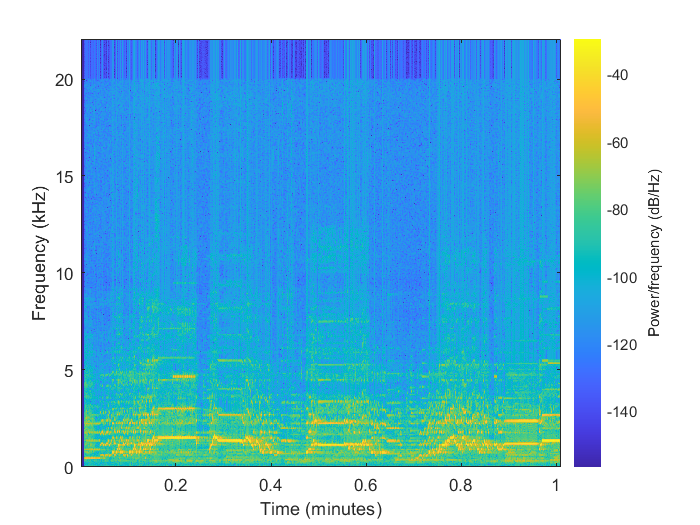

spectrogram(x, 1024, 512, 1024, fs, 'yaxis')

## Cocktail party audio analysis


[x,fs] = audioread("cocktailParty2.mp4")

x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


fs = 44100

%x = x(:,1); % considering only 1 channel
N = length(x); % N -> total number of samples
t = (0:N-1)/fs;
% fs -> number of samples per second
N/fs % gives the duration of the audio file

ans = 10.4258

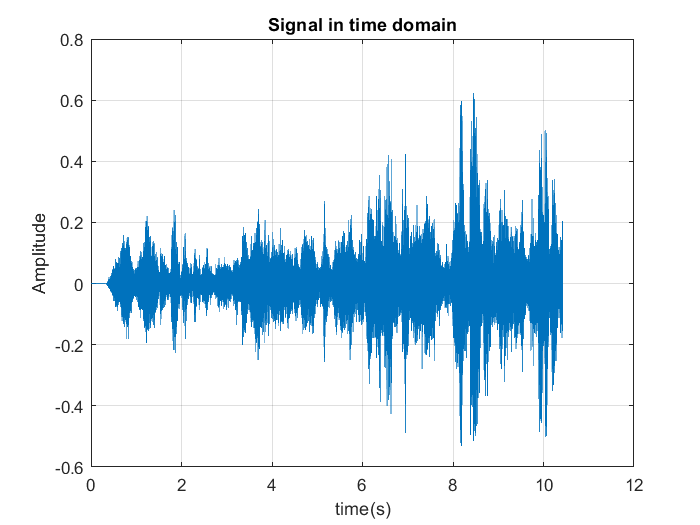

% plot time domain signal
plot(t,x)
grid on
xlabel("time(s)");
ylabel("Amplitude")
title("Signal in time domain");

% stats information
minValue = min(x)

minValue = -0.5284

maxValue = max(x)

maxValue = 0.6221

meanValue = mean(x)

meanValue = -5.8032e-04

stdValue = std(x)

stdValue = 0.0683

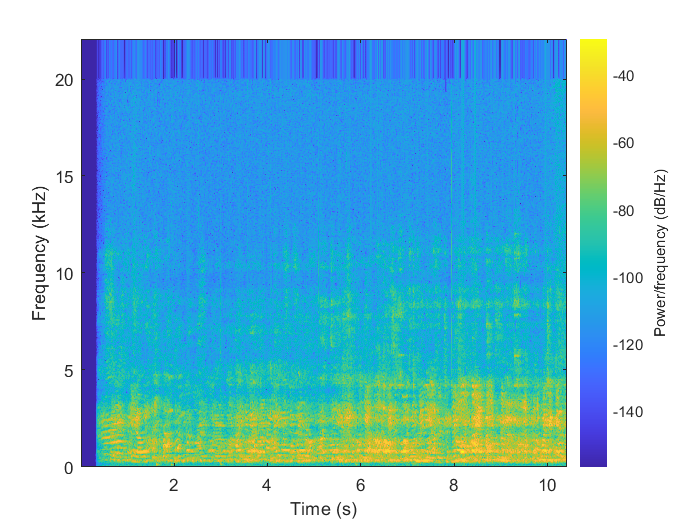

spectrogram(x, 1024, 512, 1024, fs, 'yaxis')

## Reconstruction of 2 audio signals from mixed signal using Binary masking


[mSpeech,Fs] = audioread("mSpeech.flac");
%sound(mSpeech,Fs);

[fSpeech] = audioread("fSpeech.flac");
%sound(fSpeech,Fs);

mSpeech = cat(1,mSpeech,zeros(length(fSpeech)-length(mSpeech),1));
length(mSpeech)

ans = 141280

length(fSpeech)

ans = 141280

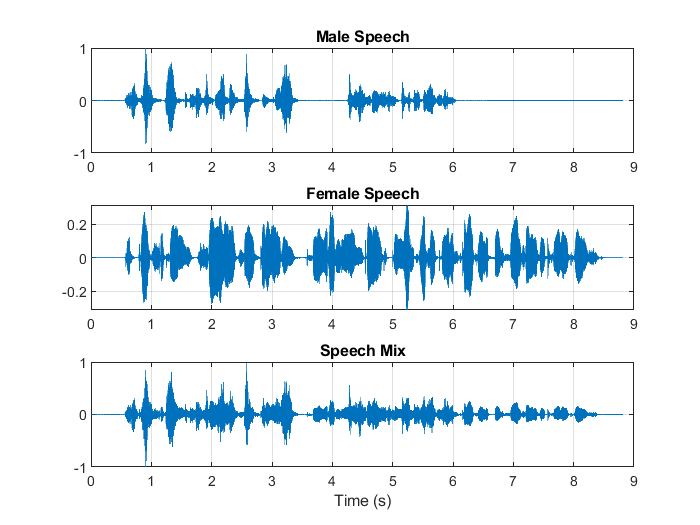


mSpeech = mSpeech/norm(mSpeech);
fSpeech = fSpeech/norm(fSpeech);
ampAdj  = max(abs([mSpeech;fSpeech]));
mSpeech = mSpeech/ampAdj;
fSpeech = fSpeech/ampAdj;
mix     = mSpeech + fSpeech;
mix     = mix ./ max(abs(mix));

t = (0:numel(mix)-1)*(1/Fs);

figure(1)
subplot(3,1,1)
plot(t,mSpeech)
title("Male Speech")
grid on
subplot(3,1,2)
plot(t,fSpeech)
title("Female Speech")
grid on
subplot(3,1,3)
plot(t,mix)
title("Speech Mix")
xlabel("Time (s)")
grid on

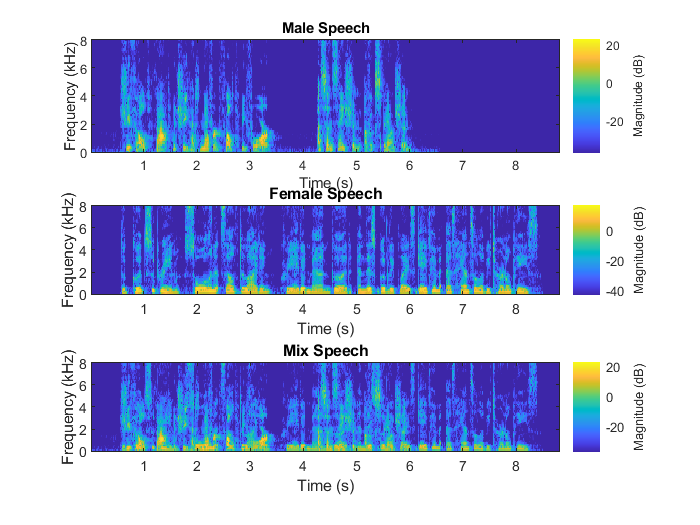


%sound(mix,Fs)

WindowLength  = 128;
FFTLength     = 128;
OverlapLength = 96;
win           = hann(WindowLength,"periodic");

figure(2)
subplot(3,1,1)
stft(mSpeech, Fs, 'Window', win,'OverlapLength',OverlapLength,...
     'FFTLength', FFTLength, 'FrequencyRange', 'onesided');
title("Male Speech")
subplot(3,1,2)
stft(fSpeech, Fs, 'Window', win, 'OverlapLength', OverlapLength,...
     'FFTLength', FFTLength, 'FrequencyRange', 'onesided');
title("Female Speech")
subplot(3,1,3)
stft(mix, Fs, 'Window', win, 'OverlapLength', OverlapLength,...
    'FFTLength', FFTLength, 'FrequencyRange', 'onesided');
title("Mix Speech")

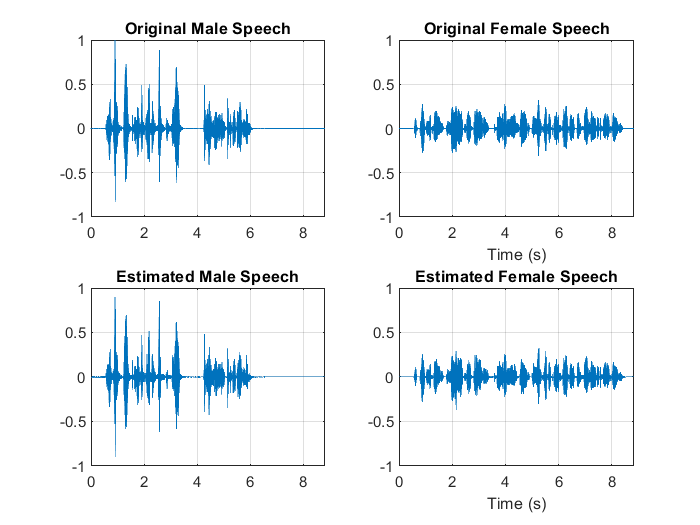


P_M        = stft(mSpeech, 'Window', win, 'OverlapLength', OverlapLength,...
                 'FFTLength', FFTLength, 'FrequencyRange', 'onesided');
P_F        = stft(fSpeech, 'Window', win, 'OverlapLength', OverlapLength,...
                 'FFTLength', FFTLength, 'FrequencyRange', 'onesided');
[P_mix,F]  = stft(mix, 'Window', win, 'OverlapLength', OverlapLength,...
                  'FFTLength', FFTLength, 'FrequencyRange', 'onesided');

binaryMask = abs(P_M) >= abs(P_F);

P_M_Hard = P_mix .* binaryMask;
P_F_Hard = P_mix .* (1-binaryMask);

mSpeech_Hard = istft(P_M_Hard, 'Window', win, 'OverlapLength', OverlapLength,...
                     'FFTLength', FFTLength, 'FrequencyRange', 'onesided');
fSpeech_Hard = istft(P_F_Hard, 'Window', win, 'OverlapLength', OverlapLength,...
                     'FFTLength', FFTLength, 'FrequencyRange', 'onesided');

figure(3)
subplot(2,2,1)
plot(t,mSpeech)
axis([t(1) t(end) -1 1])
title("Original Male Speech")
grid on

subplot(2,2,3)
plot(t,mSpeech_Hard)
axis([t(1) t(end) -1 1])
title("Estimated Male Speech")
grid on

subplot(2,2,2)
plot(t,fSpeech)
axis([t(1) t(end) -1 1])
xlabel("Time (s)")
title("Original Female Speech")
grid on

subplot(2,2,4)
plot(t,fSpeech_Hard)
axis([t(1) t(end) -1 1])
xlabel("Time (s)")
title("Estimated Female Speech")
grid on

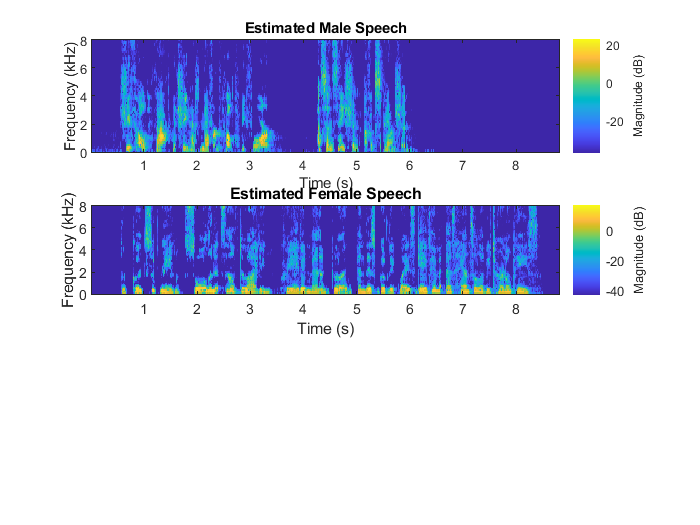


%sound(mSpeech_Hard,Fs);

%sound(fSpeech_Hard,Fs);

figure(4)
subplot(3,1,1)
stft(mSpeech_Hard, Fs, 'Window', win,'OverlapLength',OverlapLength,...
     'FFTLength', FFTLength, 'FrequencyRange', 'onesided');
title("Estimated Male Speech")
subplot(3,1,2)
stft(fSpeech_Hard, Fs, 'Window', win, 'OverlapLength', OverlapLength,...
     'FFTLength', FFTLength, 'FrequencyRange', 'onesided');
title("Estimated Female Speech")

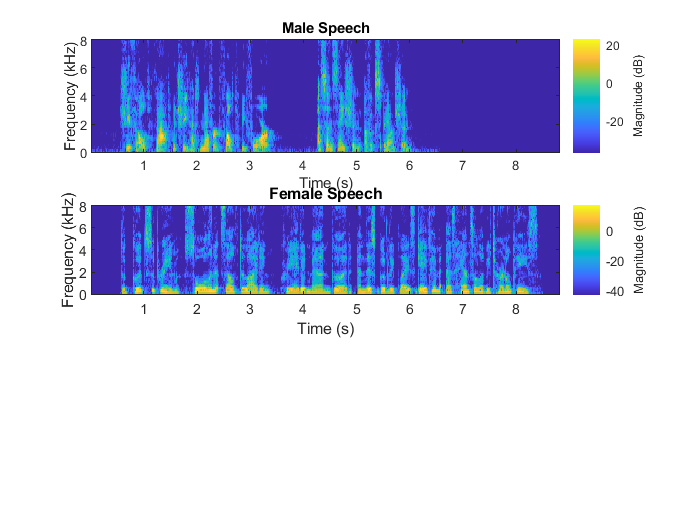


figure(5)
subplot(3,1,1)
stft(mSpeech, Fs, 'Window', win,'OverlapLength',OverlapLength,...
     'FFTLength', FFTLength, 'FrequencyRange', 'onesided');
title("Male Speech")
subplot(3,1,2)
stft(fSpeech, Fs, 'Window', win, 'OverlapLength', OverlapLength,...
     'FFTLength', FFTLength, 'FrequencyRange', 'onesided');
title("Female Speech")

## Reconstruction of 3 audio signals from a mixed signal using Soft masking


[mSpeech,Fs] = audioread("mSpeech.flac");
%sound(mSpeech,Fs);

[fSpeech] = audioread("fSpeech.flac");
%sound(fSpeech,Fs);
[fSpeech2] = audioread("fSpeech2.flac");
mSpeech = cat(1,mSpeech,zeros(length(fSpeech2)-length(mSpeech),1));
fSpeech= cat(1,fSpeech,zeros(length(fSpeech2)-length(fSpeech),1));

length(mSpeech)

ans = 142000

length(fSpeech)

ans = 142000

length(fSpeech2)

ans = 142000

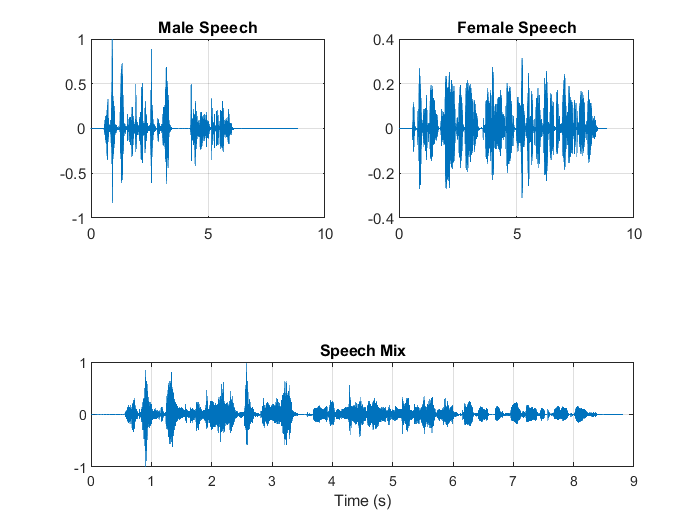


mSpeech = mSpeech/norm(mSpeech);
fSpeech = fSpeech/norm(fSpeech);
fSpeech2 = fSpeech2/norm(fSpeech2);

ampAdj  = max(abs([mSpeech;fSpeech;fSpeech2]));
mSpeech = mSpeech/ampAdj;
fSpeech = fSpeech/ampAdj;
fSpeech2 = fSpeech2/ampAdj;
mix     = mSpeech + fSpeech + fSpeech2;
mix     = mix ./ max(abs(mix));

t = (0:numel(mix)-1)*(1/Fs);
figure(1)
subplot(2,2,1)
plot(t,mSpeech)
title("Male Speech")
grid on
subplot(2,2,2)
plot(t,fSpeech)
title("Female Speech")
grid on

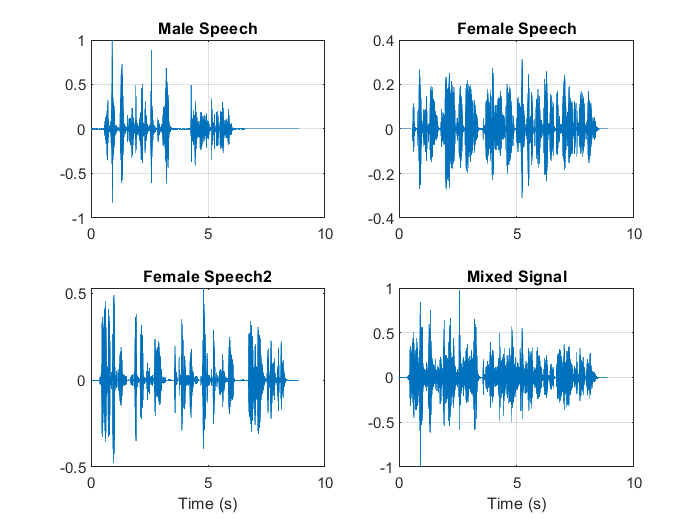

subplot(2,2,3)
plot(t,fSpeech2)
title("Female Speech2")
xlabel("Time (s)")
subplot(2,2,4)
plot(t,mix)
title("Mixed Signal")
xlabel("Time (s)")
grid on

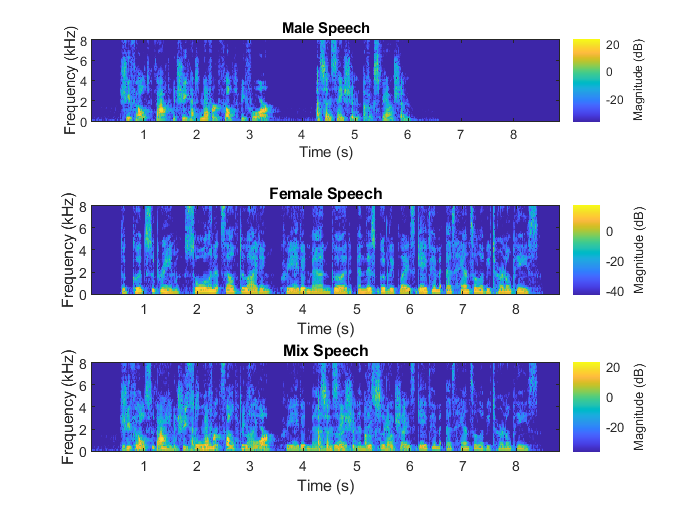


%sound(mix,Fs)

WindowLength  = 128;
FFTLength     = 128;
OverlapLength = 96;
win           = hann(WindowLength,"periodic");

figure(2)
subplot(4,1,1)
stft(mSpeech, Fs, 'Window', win,'OverlapLength',OverlapLength,...
     'FFTLength', FFTLength, 'FrequencyRange', 'onesided');
title("Male Speech")

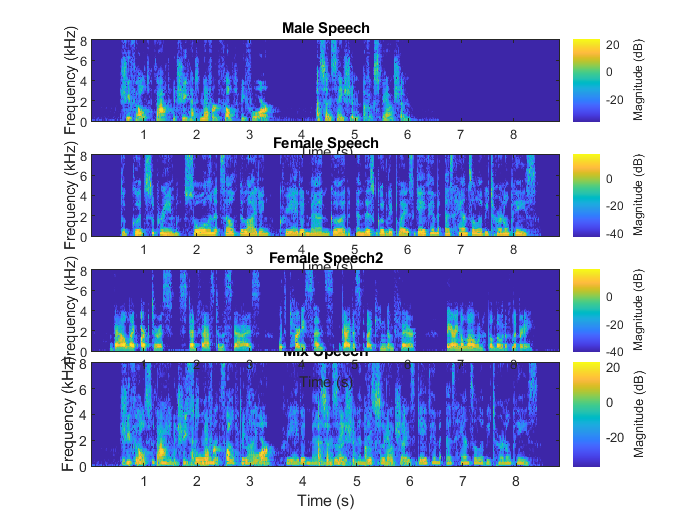

subplot(4,1,2)
stft(fSpeech, Fs, 'Window', win, 'OverlapLength', OverlapLength,...
     'FFTLength', FFTLength, 'FrequencyRange', 'onesided');
title("Female Speech")
subplot(4,1,3)
stft(fSpeech2, Fs, 'Window', win, 'OverlapLength', OverlapLength,...
     'FFTLength', FFTLength, 'FrequencyRange', 'onesided');
title("Female Speech2")

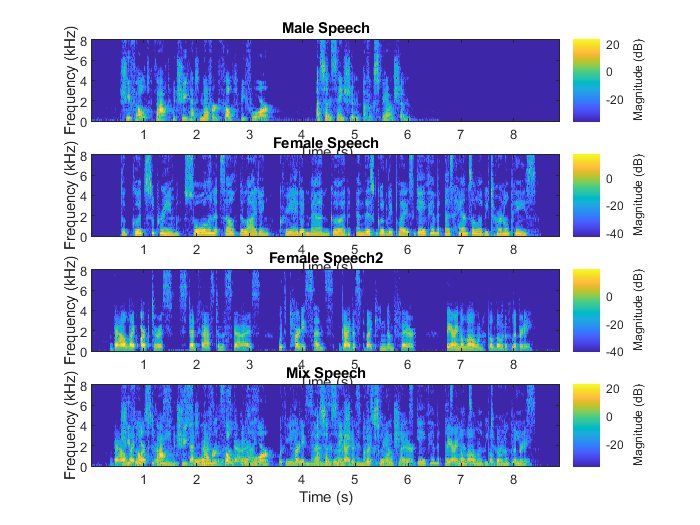

subplot(4,1,4)
stft(mix, Fs, 'Window', win, 'OverlapLength', OverlapLength,...
    'FFTLength', FFTLength, 'FrequencyRange', 'onesided');
title("Mix Speech")

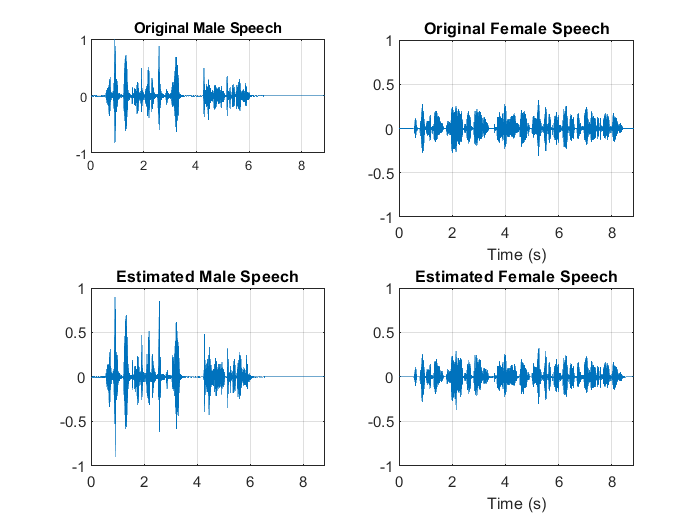


P_M        = stft(mSpeech, 'Window', win, 'OverlapLength', OverlapLength,...
                 'FFTLength', FFTLength, 'FrequencyRange', 'onesided');
P_F        = stft(fSpeech, 'Window', win, 'OverlapLength', OverlapLength,...
                 'FFTLength', FFTLength, 'FrequencyRange', 'onesided');
P_F2        = stft(fSpeech2, 'Window', win, 'OverlapLength', OverlapLength,...
                 'FFTLength', FFTLength, 'FrequencyRange', 'onesided');

[P_mix,F]  = stft(mix, 'Window', win, 'OverlapLength', OverlapLength,...
                  'FFTLength', FFTLength, 'FrequencyRange', 'onesided');

softMask1 = abs(P_M) ./ (abs(P_F) + abs(P_F2) + abs(P_M) + eps);
softMask2 = abs(P_F) ./ (abs(P_F) + abs(P_F2) + abs(P_M) + eps);
softMask3 = abs(P_F2) ./ (abs(P_F) + abs(P_F2) + abs(P_M) + eps);
P_M_Soft = P_mix .* softMask1;
P_F_Soft = P_mix .* softMask2;
P_F2_Soft=P_mix .* softMask3;

mSpeech_Soft = istft(P_M_Soft, 'Window', win, 'OverlapLength', OverlapLength,...
                     'FFTLength', FFTLength, 'FrequencyRange', 'onesided');
fSpeech_Soft = istft(P_F_Soft, 'Window', win, 'OverlapLength', OverlapLength,...
                     'FFTLength', FFTLength, 'FrequencyRange', 'onesided');
fSpeech2_Soft = istft(P_F2_Soft, 'Window', win, 'OverlapLength', OverlapLength,...
                     'FFTLength', FFTLength, 'FrequencyRange', 'onesided');
mSpeech_Soft=cat(1,mSpeech_Soft,zeros(length(t)-length(mSpeech_Soft),1));
fSpeech_Soft=cat(1,fSpeech_Soft,zeros(length(t)-length(fSpeech_Soft),1));
fSpeech2_Soft=cat(1,fSpeech2_Soft,zeros(length(t)-length(fSpeech2_Soft),1));

figure(3)
subplot(3,2,1)
plot(t,mSpeech)
axis([t(1) t(end) -1 1])
title("Original Male Speech")
grid on

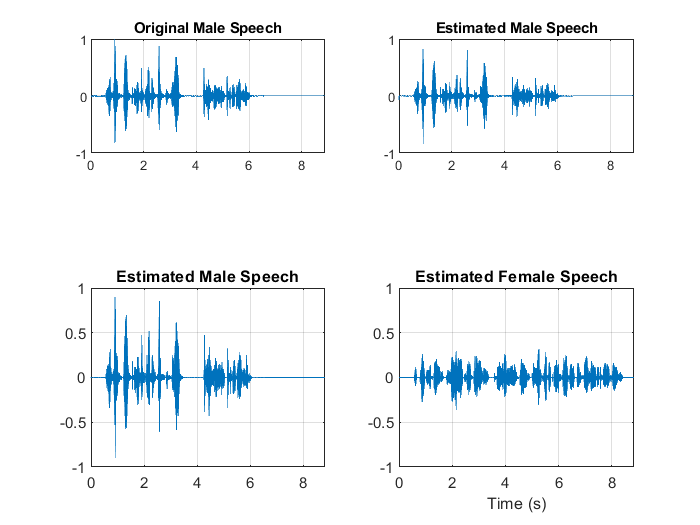


subplot(3,2,2)
plot(t,mSpeech_Soft)
axis([t(1) t(end) -1 1])
title("Estimated Male Speech")
grid on

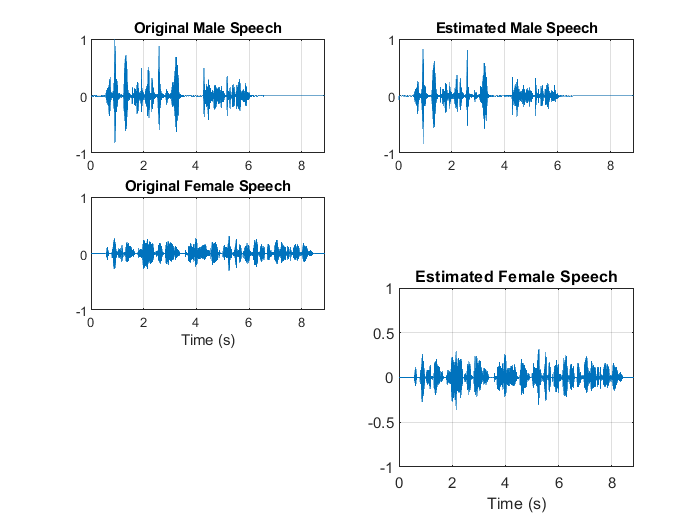


subplot(3,2,3)
plot(t,fSpeech)
axis([t(1) t(end) -1 1])
xlabel("Time (s)")
title("Original Female Speech")
grid on

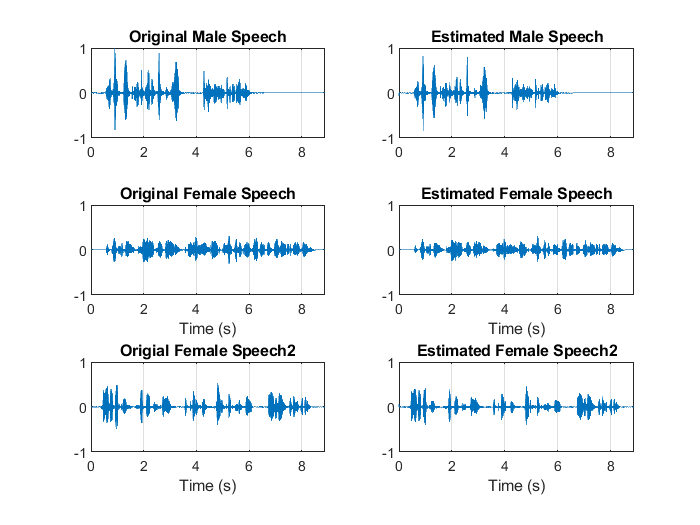


subplot(3,2,4)
plot(t,fSpeech_Soft)
axis([t(1) t(end) -1 1])
xlabel("Time (s)")
title("Estimated Female Speech")
grid on
subplot(3,2,5)
plot(t,fSpeech2)
axis([t(1) t(end) -1 1])
xlabel("Time (s)")
title("Origial Female Speech2")
grid on
subplot(3,2,6)
plot(t,fSpeech2_Soft)
axis([t(1) t(end) -1 1])
xlabel("Time (s)")
title("Estimated Female Speech2")
grid on

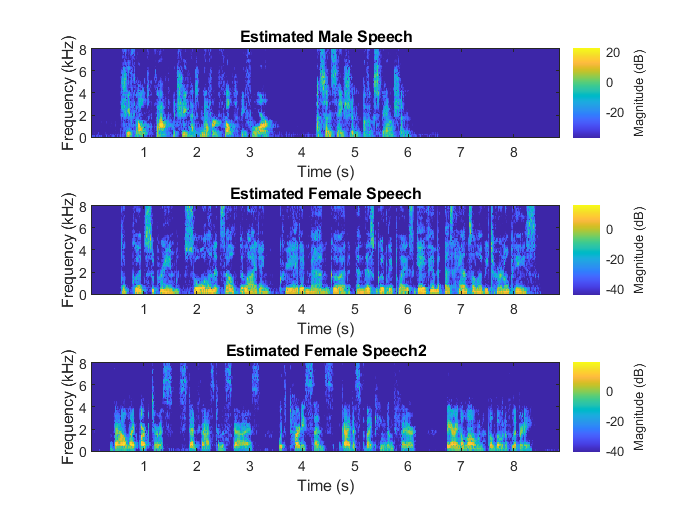


%sound(mSpeech_Soft,Fs);

%sound(fSpeech_Soft,Fs);

figure(4)
subplot(3,1,1)
stft(mSpeech_Soft, Fs, 'Window', win,'OverlapLength',OverlapLength,...
     'FFTLength', FFTLength, 'FrequencyRange', 'onesided');
title("Estimated Male Speech")
subplot(3,1,2)
stft(fSpeech_Soft, Fs, 'Window', win, 'OverlapLength', OverlapLength,...
     'FFTLength', FFTLength, 'FrequencyRange', 'onesided');
title("Estimated Female Speech")
subplot(3,1,3)
stft(fSpeech2_Soft, Fs, 'Window', win, 'OverlapLength', OverlapLength,...
     'FFTLength', FFTLength, 'FrequencyRange', 'onesided');
title("Estimated Female Speech2")